# Training data 

More on [https://github.com/slevin48/gta](https://github.com/slevin48/gta) 

## Data access

### Get Data from dumped images

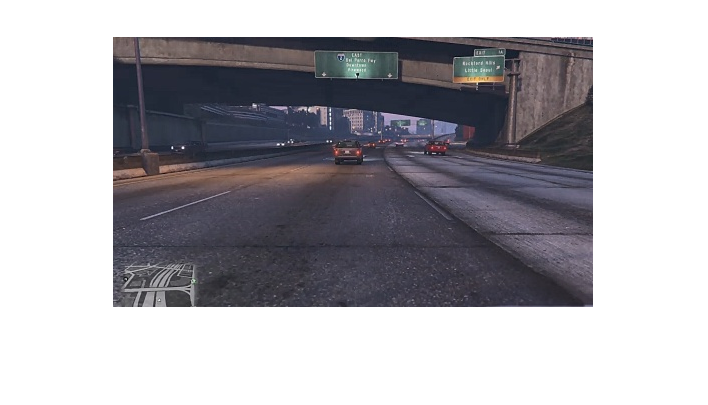

training_dataset = "training_data-2021-02-12-3";
sequence = 1;
training_data_0 = imread("screenshots\"+training_dataset+"\screenshots"+string(sequence)+"\training_data_0.jpg");
imshow(training_data_0)

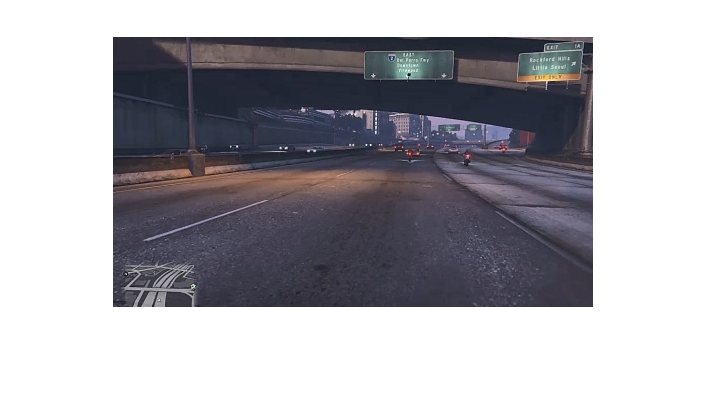

i = 281;
training_img = imread("screenshots\"+training_dataset+"\screenshots"+string(sequence)+"\training_data_"+string(i)+".jpg");
imshow(training_img)

timeline = readtable("timeline\training_data-2021-02-12-3\timeline"+string(sequence)+".csv")

timeline = 500×2 table
    Var1             time          
    ____    _______________________

      0     2021-02-12 20:00:06.538
      1     2021-02-12 20:00:06.568
      2     2021-02-12 20:00:06.585
      3     2021-02-12 20:00:06.602
      4     2021-02-12 20:00:06.617
      5     2021-02-12 20:00:06.637
      6     2021-02-12 20:00:06.654
      7     2021-02-12 20:00:06.686
      8     2021-02-12 20:00:06.703
      9     2021-02-12 20:00:06.719
     10     2021-02-12 20:00:06.734
     11     2021-02-12 20:00:06.752
     12     2021-02-12 20:00:06.768
     13     2021-02-12 20:00:06.784
     14     2021-02-12 20:00:06.801
     15     2021-02-12 20:00:06.818


keyboard = readtable("keyboard\"+training_dataset+"\training_data-"+string(sequence)+".csv")

keyboard = 500×10 table
    Var1    Z    S    Q    D    ZQ    ZD    SQ    SD    NOKEY
    ____    _    _    _    _    __    __    __    __    _____

      0     1    0    0    0    0     0     0     0       0  
      1     1    0    0    0    0     0     0     0       0  
      2     1    0    0    0    0     0     0     0       0  
      3     1    0    0    0    0     0     0     0       0  
      4     1    0    0    0    0     0     0     0       0  
      5     1    0    0    0    0     0     0     0       0  
      6     1    0    0    0    0     0     0     0       0  
      7     1    0    0    0    0     0     0     0       0  
      8     1  

i = 353;
training_img = imread("screenshots\training_data-2021-02-12-3\screenshots1\training_data_"+string(i)+".jpg");
timeline(i,"time").time

ans = datetime
   2021-02-12 20:00:14.407


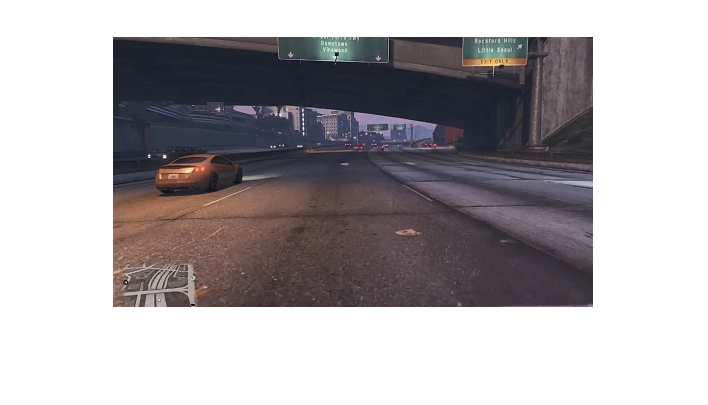

imshow(training_img)

### Get controller inputs

We have 2 options:

- Get the controller input directly with [https://github.com/komefai/PS4Macro](https://github.com/komefai/PS4Macro)

- Map the command to the Keyboard with [https://github.com/starshinata/PS4-Keyboard-and-Mouse-Adapter](https://github.com/starshinata/PS4-Keyboard-and-Mouse-Adapter)

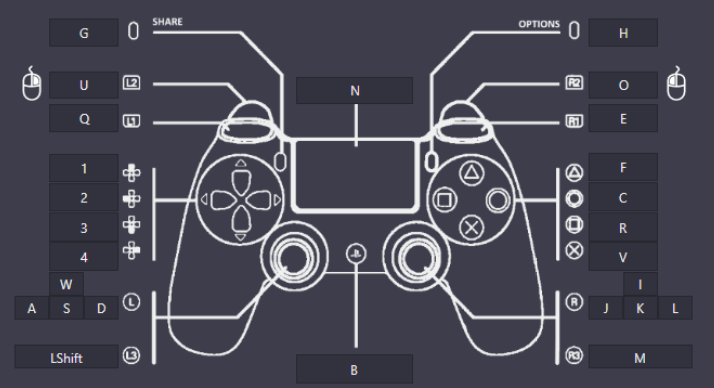

The folder `ps4_macro `contains the controller record and python functions:

py.os.chdir("ps4_macro");
% py.os.chdir("..")
cwd = py.os.getcwd()

cwd =   Python str with no properties.

    C:\Users\ydebray\Downloads\gta\ps4_macro


`PS4_control.py` provides 2 functions to: 

- **read** XML controller file as DataFrame, 

- **save** it as Excel file

df = py.PS4_control.read_controller("2021-02-12-3.xml");
py.PS4_control.save_controller(df,"2021-02-12-3.xlsx")

py.os.chdir("..")
% py.os.getcwd()

% Specify column names and types
opts = spreadsheetImportOptions("NumVariables", 33);
opts.DataRange = "B2";
opts.VariableNames = ["ReportTimeStamp", "LX", "LY", "RX", "RY", "L2", "R2", "Triangle", "Circle", "Cross", "Square", "DPad_Up", "DPad_Down", "DPad_Left", "DPad_Right", "L1", "R1", "Share", "Options", "L3", "R3", "PS", "TouchButton", "TouchPacketCounter", "FrameCounter", "Battery", "IsCharging", "AccelX", "AccelY", "AccelZ", "GyroX", "GyroY", "GyroZ"];
opts.VariableTypes = ["string", "double", "double", "double", "double", "double", "double", "categorical", "categorical", "categorical", "categorical", "categorical", "categorical", "categorical", "categorical", "categorical", "categorical", "categorical", "categorical", "categorical", "categorical", "categorical", "categorical", "double", "double", "double", "categorical", "double", "double", "double", "double", "double", "double"];

T = readtable("ps4_macro/2021-02-12-3.xlsx",opts);
T.ReportTimeStamp = datetime(T.ReportTimeStamp,"InputFormat","uuuu-MM-dd'T'HH:mm:ss.SSSSSSS'Z'");
T.ReportTimeStamp.Format = 'MMM dd, yyyy HH:mm:ss.SSS'

T = 14565×33 table
         ReportTimeStamp         LX     LY     RX     RY     L2    R2    Triangle    Circle    Cross    Square    DPad_Up    DPad_Down    DPad_Left    DPad_Right     L1       R1      Share    Options     L3       R3       PS      TouchButton    TouchPacketCounter    FrameCounter    Battery    IsCharging    AccelX    AccelY    AccelZ    GyroX    GyroY    GyroZ
    _________________________    

The conversion does keep the fractional seconds. However, by default `datetime` arrays do not *display* fractional seconds. To display them, specify either the `'Format'` name-value pair or the `Format` property.

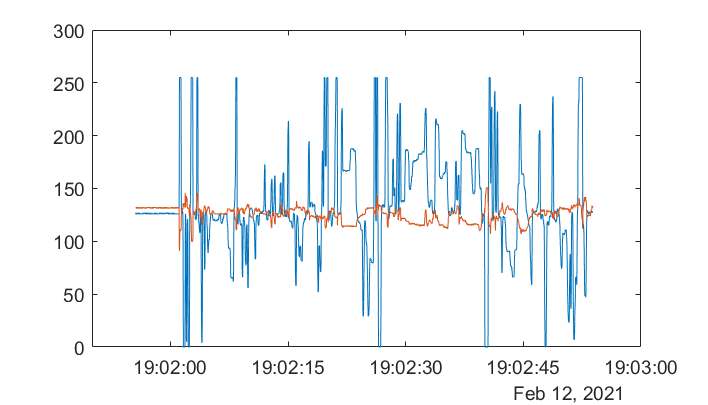

plot(T.ReportTimeStamp,[T.LX,T.LY])

The ReportTimeStamp has an offset with the timestamp from the video record

**Go further: **[Synchronizing Time-Series Data Using MATLAB - YouTube](https://www.youtube.com/watch?v=ltheBeYpCxs&ab_channel=MATLAB)

### Get keyboard inputs

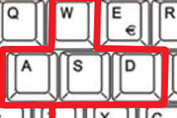

**/!\**** Q instead of A for French keyboard here!!!**

T = readtable("keyboard/"+training_dataset+"/training_data-1.csv");
T = renamevars(T,"Var1","ID")

T = 500×10 table
    ID    Z    S    Q    D    ZQ    ZD    SQ    SD    NOKEY
    __    _    _    _    _    __    __    __    __    _____

     0    1    0    0    0    0     0     0     0       0  
     1    1    0    0    0    0     0     0     0       0  
     2    1    0    0    0    0     0     0     0       0  
     3    1    0    0    0    0     0     0     0       0  
     4    0    0    0    0    0     0     0     0       1  
     5    0    0    0    0    0     0     0     0       1  
     6    1    0    0    0    0     0     0     0       0  
     7    1    0    0    0    0     0     0     0       0  
     8    1    0    0    0    0     0     

T(T.D == 1,:) % Turning right

ans = 18×10 table
    ID     W    S    Q    D    WQ    WD    SQ    SD    NOKEY
    ___    _    _    _    _    __    __    __    __    _____

    212    0    0    0    1    0     0     0     0       0  
    213    0    0    0    1    0     0     0     0       0  
    214    0    0    0    1    0     0     0     0       0  
    215    0    0    0    1    0     0     0     0       0  
    216    0    0    0    1    0     0     0     0       0  
    359    0    0    0    1    0     0     0     0       0  
    360    0    0    0    1    0     0     0     0       0  
    361    0    0    0    1    0     0     0     0       0  
    362    0    0    0    1    

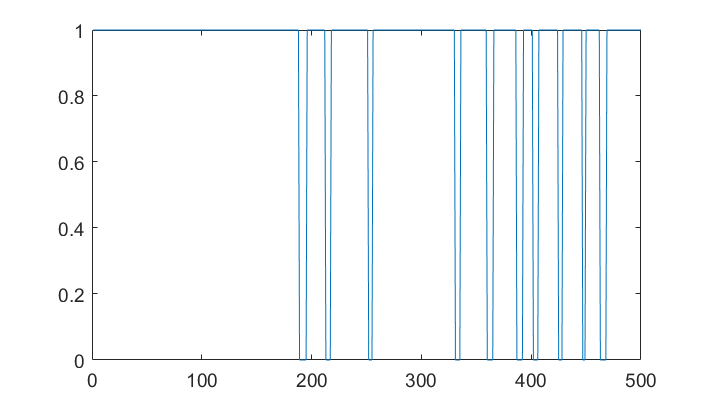

plot(T.NOKEY)

### Get data from Numpy directly

pyenv

training_dir = 'D:\training_data-2021-02-12-2'

training_dir = uigetdir

npfiles = 23×1 struct array with fields:
    name
    folder
    date
    bytes
    isdir
    datenum


% training_dataset"training_data-2021-02-12-2"

ans = 23

% training_dir = "training_data\"+training_dataset

npfiles = dir(training_dir+"\*.npy")
length(npfiles)

npfile = 3;

npdata =   Python list with no properties.

    [array([[[223, 218, 219],
            [223, 218, 219],
            [223, 218, 219],
            ...,
            [ 52,  48,  59],
            [121, 108, 113],
            [183, 159, 154]],
    
           [[223, 218, 219],
            [223, 218, 219],
            [223, 218, 219],
            ...,
            [ 52,  47,  56],
            [119, 108, 113],
            [186, 163, 157]],
    
           [[223, 219, 218],
            [223, 219, 218],
            [223, 219, 218],
            ...,
            [ 53,  45,  53],
            [131, 117, 120],
            [196, 173, 164]],
    
           ...,
    
           [[185, 207, 217],
            [183, 205, 216],
            [178, 200, 211],
            ...,
            [119, 136, 139],
            [111, 128, 131],
            [118, 135, 138]],
    
           [[187, 209, 220],
            [189, 211, 222],
            [188, 211, 2

% npdata = py.numpy.load("training_data\training_data-"+string(nb_train)+".npy")

mdata = 1×500 cell array
  Columns 1 through 384

    {1×1 py.numpy.ndarray}    {1×1 py.numpy.ndarray}    {1×1 py.numpy.ndarray}    {1×1 py.numpy.ndarray}    {1×1 py.numpy.ndarray}    {1×1 py.numpy.ndarray}    {1×1 py.numpy.ndarray}    {1×1 py.numpy.ndarray}    {1×1 py.numpy.ndarray}    {1×1 py.numpy.ndarray}    {1×1 py.numpy.ndarray}    {1×1 py.numpy.ndarray}    {1×1 py.numpy.ndarray}    {1×1 py.numpy.ndarray}    {1×1 py.numpy.ndarray}    {1×1 py.numpy.ndarray}    {1×1 py.numpy.ndarray}    {1×1 py.numpy.ndarray}    {1×1 py.numpy.ndarray}    {1×1 py.numpy.ndarray}    {1×1 py.numpy.ndarray}    {1×1 py.numpy.ndarray}    {1×1 py.numpy.ndarray}    {1×1 py.numpy.ndarray}    {1×1 py.numpy.ndarray}    {1×1 py.numpy.ndarray}    {1×1 py.numpy.ndarray}    {1×1 py.numpy.ndarray}    {1×1 py.numpy.ndarray}    {1×1 py.numpy.ndarray}    {1×1 py.numpy.ndarray}    {1×1 py.numpy.ndarray}    {1×1 py.numpy.ndarray}    {1×1 py.numpy.ndarray}    {1×1 py.numpy.ndarray}    {1×1 py.numpy.ndarray}    {1×1 py.nu

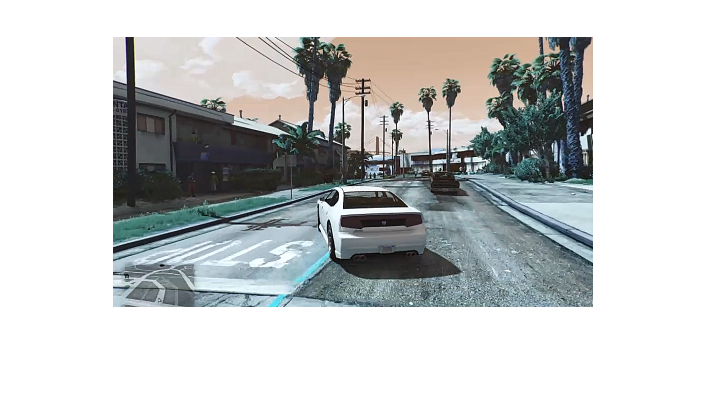

npdata = py.training_data.load_data(training_dir+"/training_data-"+string(npfile)+".npy")

mdata = cell(npdata)
imshow(uint8(mdata{1}))

### Browse training data with an app

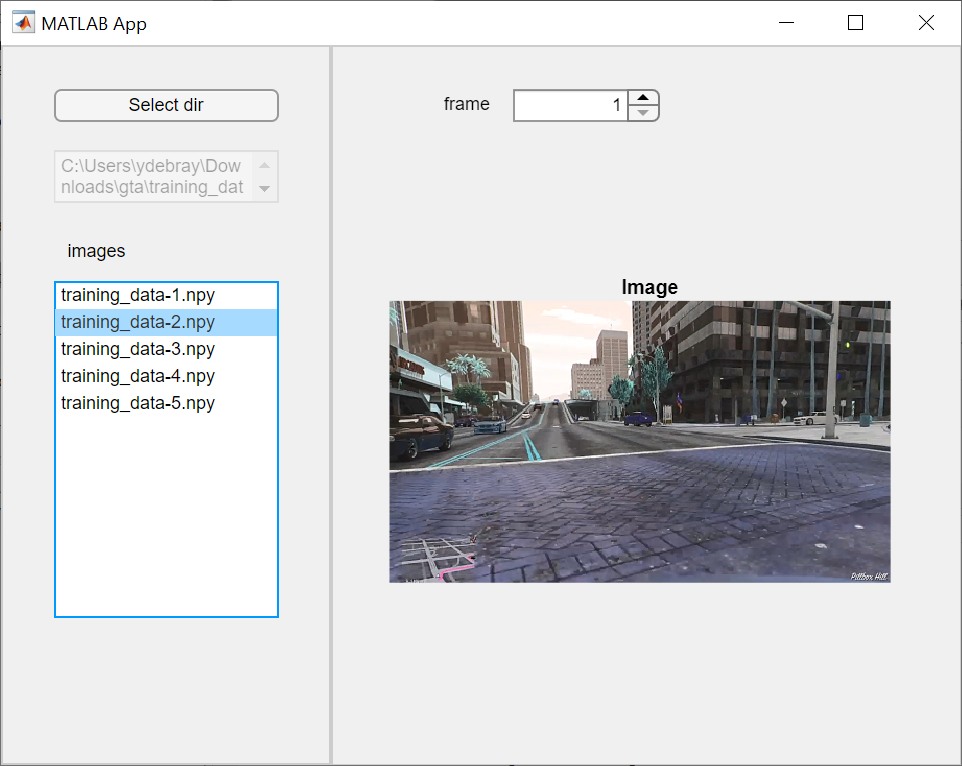

### Specify data

k = 2;
dataFolder = "screenshots\"+training_dataset+"\screenshots"+string(k);
% renameImages(dataFolder); % only need to be run once
imds = imageDatastore(dataFolder);

## Modelling

### Aside : what does a pre-trained ACF detector give us ?

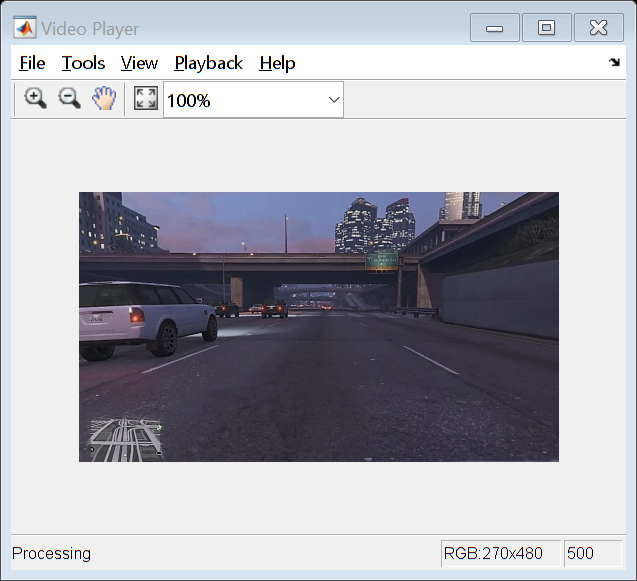

detector = vehicleDetectorACF('front-rear-view');
vp = vision.VideoPlayer ;

reset(imds);
reset(vp)
while hasdata( imds )
    I = read( imds );
    [bboxes,scores] = detect(detector,I);
    if ~isempty( bboxes )
        I = insertObjectAnnotation(I,'rectangle',bboxes,scores);
    end
    step( vp, I )
    drawnow
end 

### Deep Learning

Read in response data and reformat 

training_dataset = "training_data-2021-02-14-1";
sequence = 1;
T = readtable("keyboard/"+training_dataset+"/training_data-"+string(sequence)+".csv");
numPoints = size(T, 1);
right = T.D ;
left = T.Q ;
straight = double(~( logical( right) | logical(left) ));
labels = straight + 2*left + 3*right; 
% onehotencode()
imds.Labels = categorical(labels);

Resize input data to match network architecture

outputSize = [270 480];
auimds = augmentedImageDatastore(outputSize, imds);

### Use Deep Network Designer to do transfer learning

In this case, using AlexNet for transfer learning does not work as the training is not converging. We need more data, and also to revisit how the problem is formulated. 

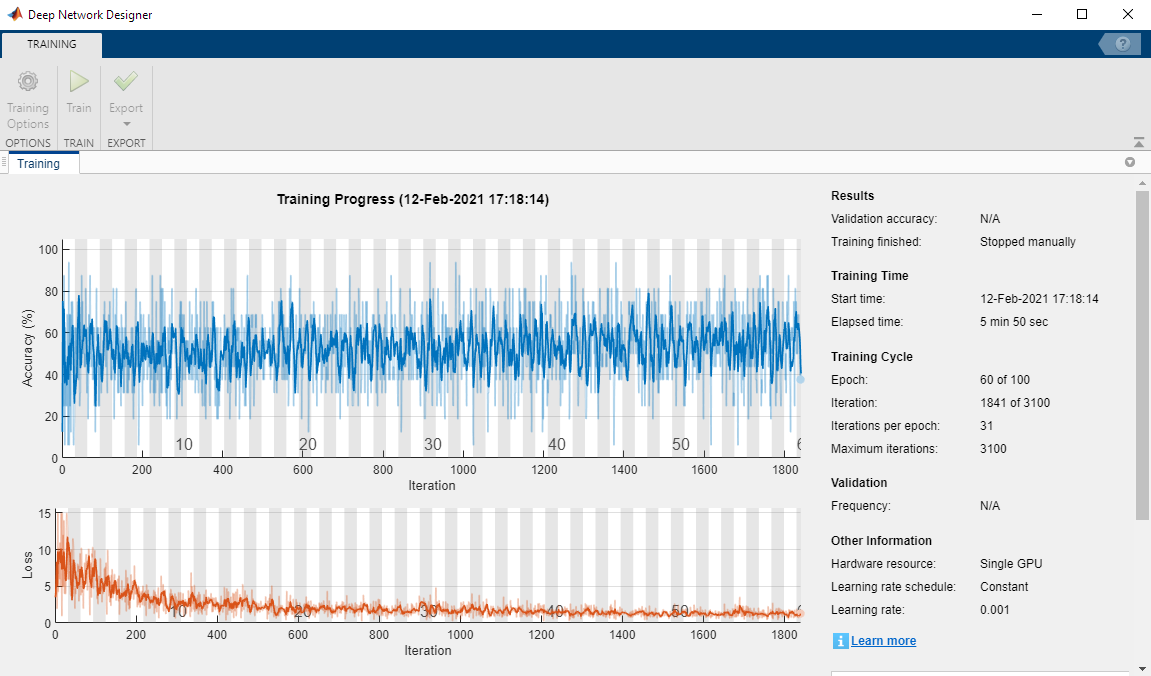

### Helper function

function renameImages( dataFolder )

D = dir(dataFolder);
nameRoot = "training_data_";
for i = 1:numel(D)
    if D(i).isdir == 0
        
        I = imread(fullfile(dataFolder, D(i).name));
        [~,filename,ext] = fileparts(D(i).name);
        nameLength = length( filename );
        if nameLength == 17
            continue;
        else
            if nameLength == 15
                imNumber = ["00" + filename(15)] ;
            elseif nameLength == 16
                imNumber = ["0" + filename(15:16)];                
            end
            newFilename = [nameRoot + imNumber + ext];
            imwrite(I, fullfile(dataFolder, newFilename));
            delete(fullfile(dataFolder, D(i).name));
        end
    end
end

end